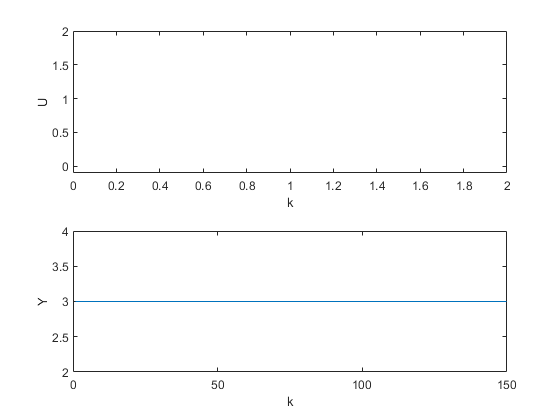

Upp = 0.9;
Vpp = 3;
Umin = 0.6;
Umax = 1.2;
Tp = 0.5;
imax = 150;
T = 1:imax;
Y = zeros(1, imax);
Y(1) = 3;
Y(2) = 3;
for i = 3:imax
    Y(i) = symulacja_obiektu2Y_p1(Upp, Upp, Y(i-1), Y(i-2));
end
subplot(2,1,1);
stairs(Upp);
xlabel('k');
ylabel('U');
hold on;
subplot(2,1,2);
stairs(Y);
xlabel('k');
ylabel('Y');
hold on;

2. 

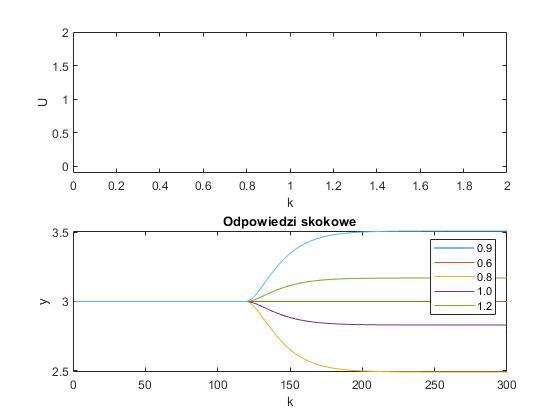

T = 1:300;
Yu = zeros(1,5);
Uu = [0.9, 0.6, 0.8, 1, 1.2];
for i = 3:300
    Y(i) = symulacja_obiektu2Y_p1(Upp, Upp, Y(i-1), Y(i-2));
end
Yu(1) = Y(120);
plot(T, Y)
hold on
for i = 121:300
    Y(i) = symulacja_obiektu2Y_p1(0.6, 0.6, Y(i-1), Y(i-2));
end
Yu(2) = Y(300);
plot(T, Y)
title("Odpowiedzi skokowe")
xlabel("k")
ylabel("y")
hold on
for i = 121:300
    Y(i) = symulacja_obiektu2Y_p1(0.8, 0.8, Y(i-1), Y(i-2));
end
Yu(3) = Y(300);
plot(T, Y)
for i = 121:300
    Y(i) = symulacja_obiektu2Y_p1(1, 1, Y(i-1), Y(i-2));
end
Yu(4) = Y(300);
plot(T, Y)
for i = 121:300
    Y(i) = symulacja_obiektu2Y_p1(1.2, 1.2, Y(i-1), Y(i-2));
end
Yu(5) = Y(300);
plot(T, Y)
legend("0.9", "0.6", "0.8", "1.0", "1.2")
hold off

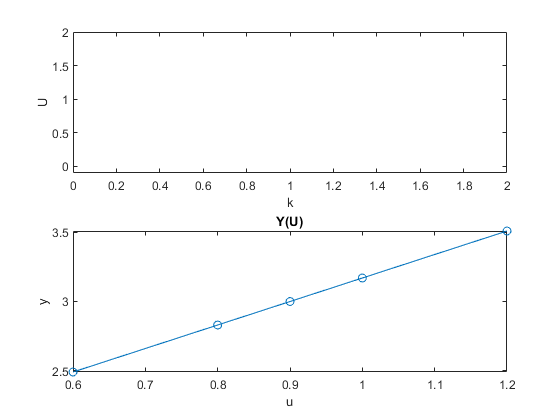

plot(Uu, Yu, "o");
title("Y(U)");
xlabel("u");
ylabel("y");
lsline;

a = (Yu(5) - Yu(1))/(Uu(5)-Uu(1)); % nie
b = Yu(5) - a*Uu(5); %nie
K = -b/a % nie 